# Machine Learning: Programming Exercise 6

## Support Vector Machines

In this exercise, you will be using support vector machines (SVMs) to build a spam classifier. 

### Files needed for this exercise

- `ex6.mlx` - MATLAB Live Script that steps you through the exercise

#### **Part 1**

- `ex6data1.mat` - Example Dataset 1

- `ex6data2.mat` - Example Dataset 2

- `ex6data3.mat` - Example Dataset 3

- `svmTrain.m` - SVM training function

- `svmPredict.m` - SVM prediction function

- `plotData.m` - Plot 2D data

- `visualizeBoundaryLinear.m` - Plot linear boundary

- `visualizeBoundary.m` - Plot non-linear boundary

- `linearKernel.m` - Linear kernel for SVM

- `submit.m` - Submission script that sends your solutions to our servers

- *`gaussianKernel.m` - Gaussian kernel for SVM

- *`dataset3Params.m` - Parameters to use for Dataset 3

#### **Part 2**

- `spamTrain.mat` - Spam training set

- `spamTest.mat` - Spam test set

- emailSample1.txt - Sample email 1

- emailSample2.txt - Sample email 2

- spamSample1.txt - Sample spam 1

- spamSample2.txt - Sample spam 2

- vocab.txt - Vocabulary list

- `getVocabList.m` - Load vocabulary list

- `porterStemmer.m` - Stemming function

- `readFile.m` - Reads a file into a character string

- `submit.m` - Submission script that sends your solutions to our servers

- *`processEmail.m` - Email preprocessing

- *`emailFeatures.m` - Feature extraction from emails

****indicates files you will need to complete***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex6' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Support Vector Machines

In the first half of this exercise, you will be using support vector machines (SVMs) with various example 2D datasets. Experimenting with these datasets will help you gain an intuition of how SVMs work and how to use a Gaussian kernel with SVMs. In the next half of the exercise, you will be using support vector machines to build a spam classifier.

### 1.1 Example dataset 1

We will begin with a 2D example dataset which can be separated by a linear boundary. The code below will plot the training data (Figure 1). In this dataset, the positions of the positive examples (indicated with +) and the negative examples (indicated with o) suggest a natural separation indicated by the gap. However, notice that there is an outlier positive example (+) on the far left at about (0:1; 4:1). As part of this exercise, you will also see how this outlier affects the SVM decision boundary.

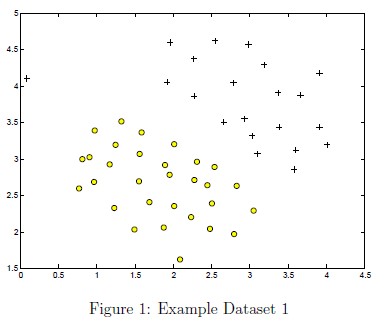

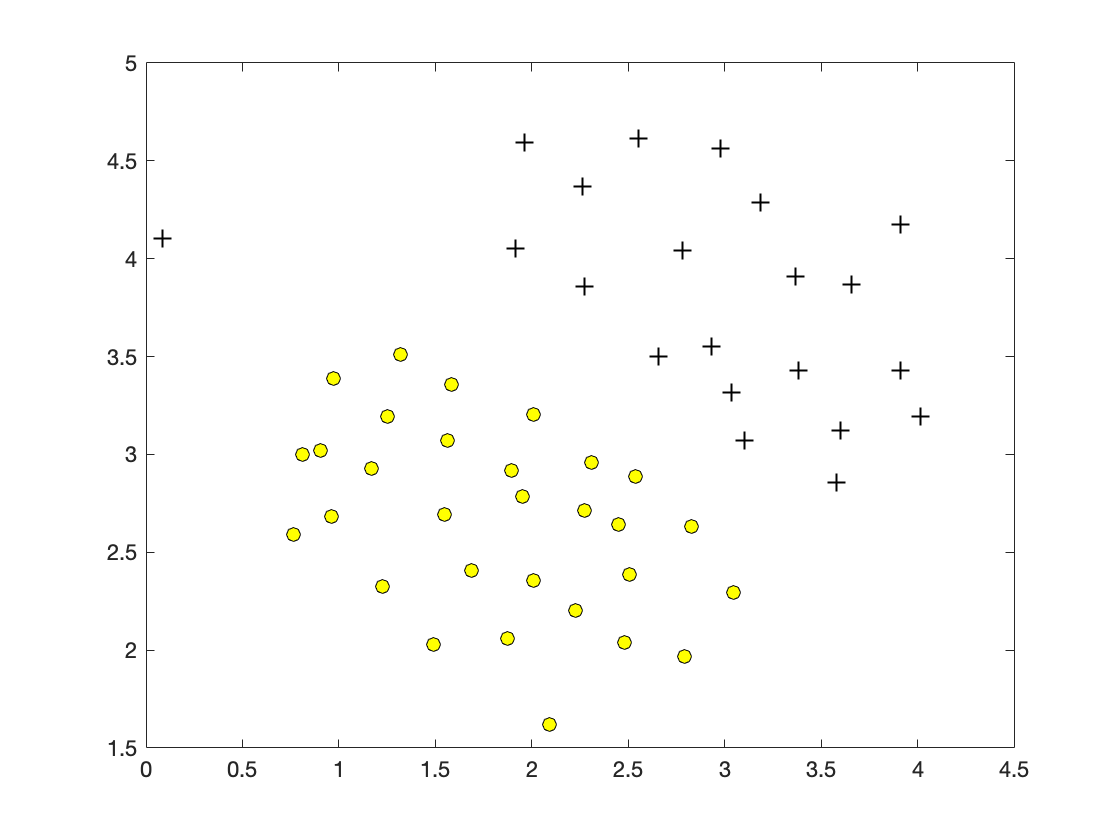

% Load from ex6data1: 
% You will have X, y in your environment
load('ex6data1.mat');

% Plot training data
plotData(X, y);

    In this part of the exercise, you will try using different values of the $C$ parameter with SVMs. Informally, the $C$ parameter is a positive value that controls the penalty for misclassiffed training examples. A large $C$ parameter tells the SVM to try to classify all the examples correctly. $C$ plays a role similar to $1/\lambda$, where $\lambda$ is the regularization parameter that we were using previously for logistic regression. The code below will run the SVM training (with $C = 1$) using SVM software that we have included with the starter code, `svmTrain.m*`. 

**Implementation Note:** Most SVM software packages (including `svmTrain.m`) automatically add the extra feature $x_0 = 1$ for you and automatically take care of learning the intercept term $\theta_0$. So when passing your training data to the SVM software, there is no need to add this extra feature $x_0 = 1$ yourself. In particular, in MATLAB your code should be working with training examples $x\in\mathbb{R}^n$ (rather than $x\in\mathbb{R}^{n+1}$) for example, in the first example dataset $x\in\mathbb{R}^2.$

C = 100;
model = svmTrain(X, y, C, @linearKernel, 1e-3, 20);


Training ......................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
.......................................

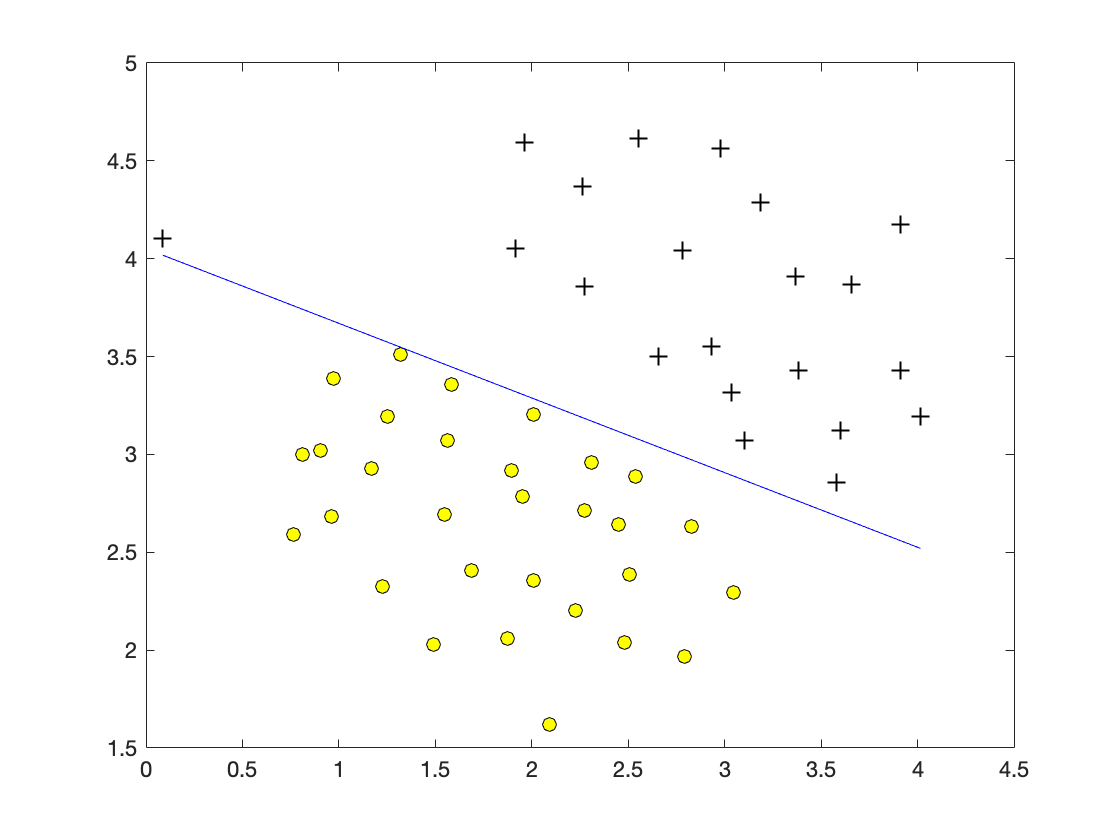

visualizeBoundaryLinear(X, y, model);

**In order to ensure compatibility with MATLAB, we have included this implementation of an SVM learning algorithm. However, this particular implementation was chosen to maximize compatibility, and is not very efficient. If you are training an SVM on a real problem, especially if you need to scale to a larger dataset, we strongly recommend instead using a highly optimized SVM toolbox such as *[*LIBSVM*](http://www.csie.ntu.edu.tw/~cjlin/libsvm/)* or the functionality available in the MATLAB Statistics and Machine Learning Toolbox for *[*efficiently training SVM's*](https://www.mathworks.com/help/stats/support-vector-machine-classification.html)*. See the MATLAB companion script for this exercise for more information and examples.*

When $C = 1$, you should find that the SVM puts the decision boundary in the gap between the two datasets and misclassifies the data point on the far left (Figure 2).

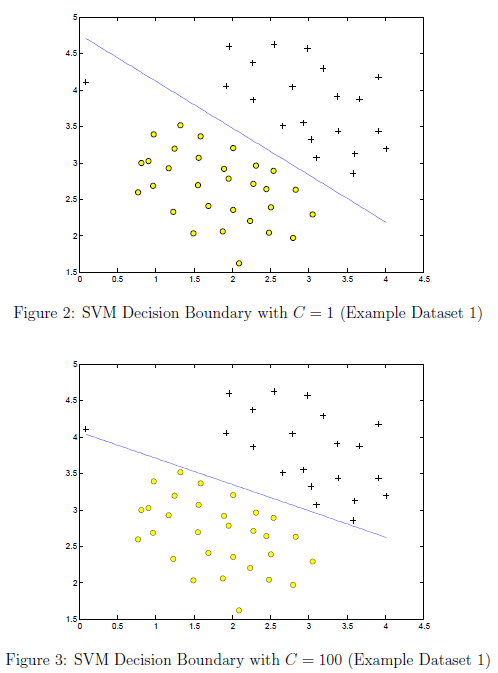

Your task is to try different values of $C$ on this dataset. Specifically, use the control to change the value of $C$ in the script to $C = 100$ and run the SVM training code in the previous section again. When $C = 100$, you should find that the SVM now classifies every single example correctly, but has a decision boundary that does not appear to be a natural fit for the data (Figure 3).

### 1.2 SVM with gaussian kernels

In this part of the exercise, you will be using SVMs to do non-linear classification. In particular, you will be using SVMs with Gaussian kernels on datasets that are not linearly separable.

#### 1.2.1 Gaussian kernel

To find nonlinear decision boundaries with the SVM, we need to first implement a Gaussian kernel. You can think of the Gaussian kernel as a similarity function that measures the 'distance' between a pair of examples, $(x^{(i)}, x^{(j)})$. The Gaussian kernel is also parameterized by a bandwidth parameter, $\sigma$, which determines how fast the similarity metric decreases (to 0) as the examples are further apart.

    You should now complete the code in `gaussianKernel.`m to compute the Gaussian kernel between two examples, $(x^{(i)}, x^{(j)})$. The Gaussian kernel function is dened as:


$$K_{gaussian}(x^{(i)},x^{(j)})
=\exp\left(-\frac{\left\| x^{(i)}-x^{(j)}\right\|^2}{2\sigma^2}\right)
=\exp\left(-\frac{\sum_{k=1}^n{(x_k^{(i)}-x_k^{(j)})^2}}{2\sigma^2}\right)$$


    Once you've completed the function `gaussianKernel.m`, run the code below to test your kernel function on two provided examples, you should expect to see a value of 0.324652 with `sigma` set to 2.

x1 = [1 2 1]; x2 = [0 4 -1]; 
sigma = 2;
sim = gaussianKernel(x1, x2, sigma);
fprintf('Gaussian Kernel between x1 = [1; 2; 1], x2 = [0; 4; -1], sigma = %f : \n\t%g\n', sigma, sim);

Gaussian Kernel between x1 = [1; 2; 1], x2 = [0; 4; -1], sigma = 2.000000 : 
	0.324652


Use the control to try different values of the parameter $\sigma$. How does the output change as $\sigma$ is increased? Decreased?

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 1.2.2 Example dataset 2

The next code section will load and plot dataset 2 (Figure 4). From the figure, you can observe that there is no linear decision boundary that separates the positive and negative examples for this dataset. 

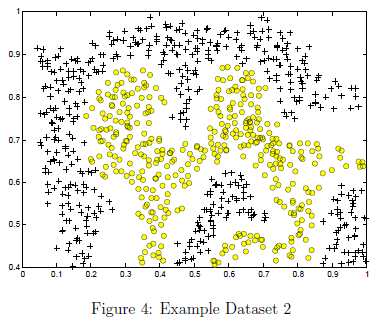

However, by using the Gaussian kernel with the SVM, you will be able to learn a non-linear decision boundary that can perform reasonably well for the dataset.

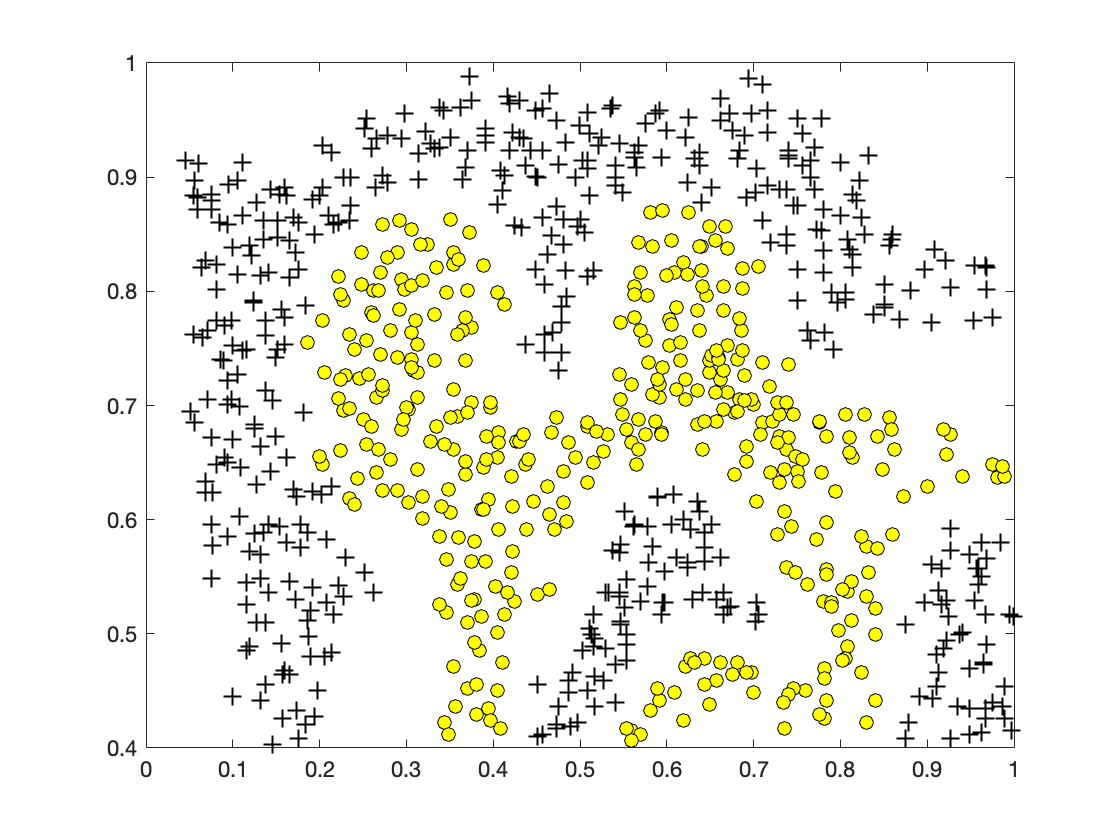

% Load from ex6data2: 
% You will have X, y in your environment
load('ex6data2.mat');

% Plot training data
plotData(X, y);   

 If you have correctly implemented the Gaussian kernel function, the code below will proceed to train the SVM with the Gaussian kernel on this dataset.

% SVM Parameters
C = 1; sigma = 0.1;

% We set the tolerance and max_passes lower here so that the code will run faster. However, in practice, 
% you will want to run the training to convergence.
model= svmTrain(X, y, C, @(x1, x2) gaussianKernel(x1, x2, sigma)); 


Training ......................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
............................ Done! 



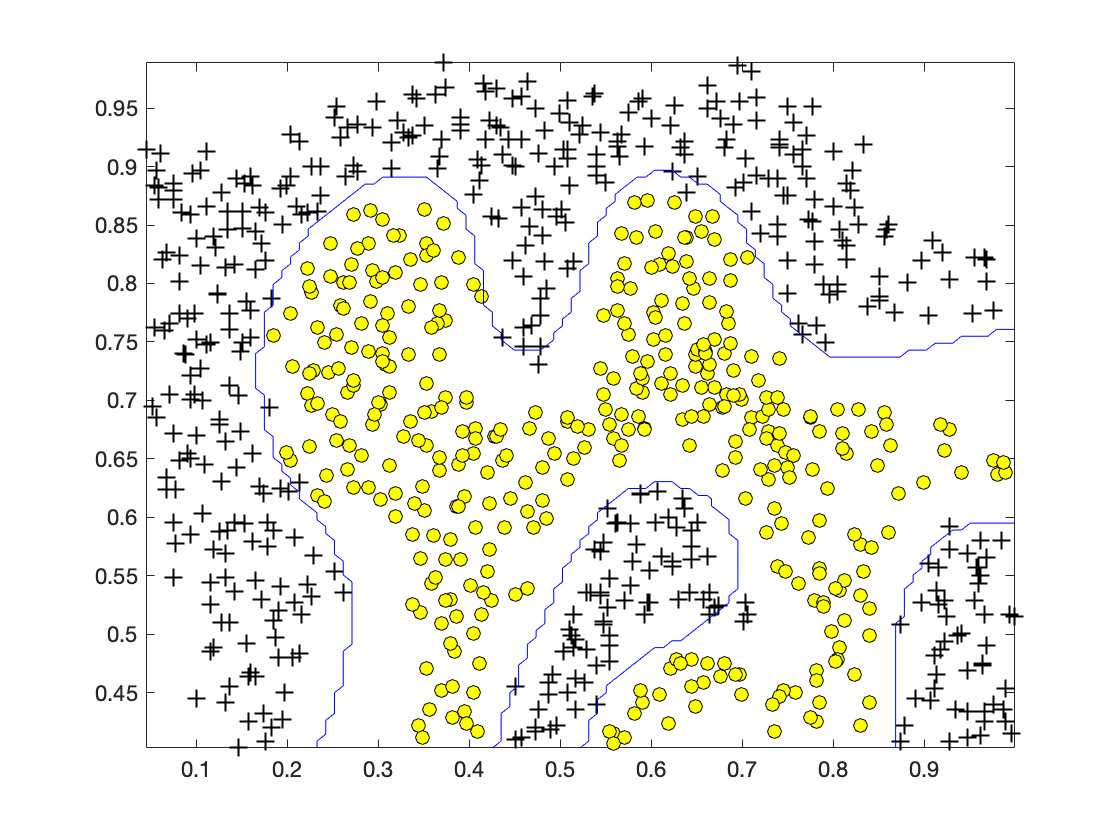

visualizeBoundary(X, y, model);

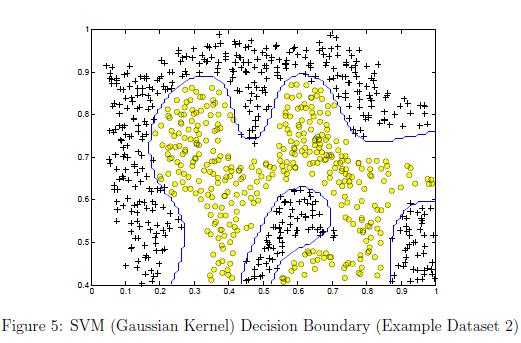

Figure 5 shows the decision boundary found by the SVM with a Gaussian kernel. The decision boundary is able to separate most of the positive and negative examples correctly and follows the contours of the dataset well.

#### 1.2.3 Example dataset 3

In this part of the exercise, you will gain more practical skills on how to use a SVM with a Gaussian kernel. The code below will load and display a third dataset (Figure 6). 

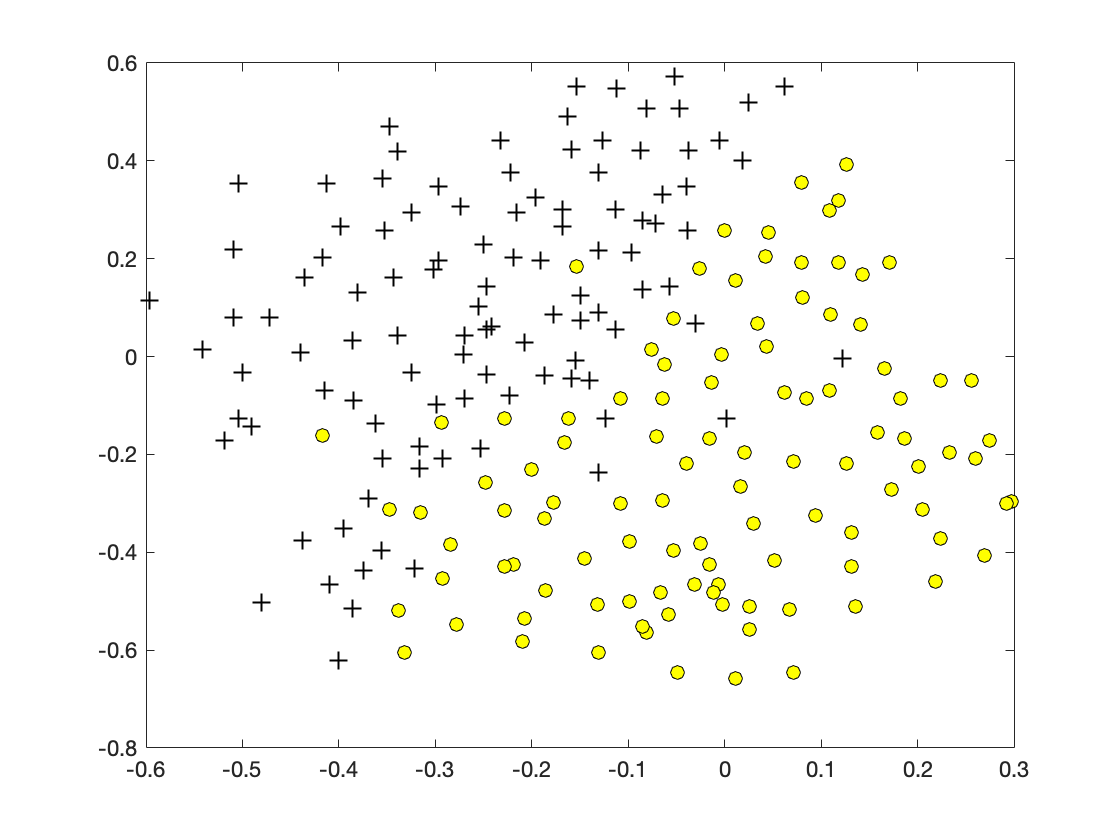

% Load from ex6data3: 
% You will have X, y in your environment
load('ex6data3.mat');

% Plot training data
plotData(X, y);

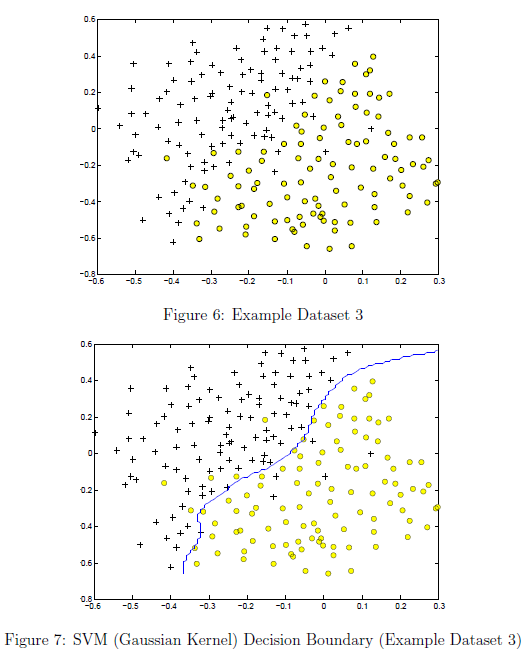

You will be using the SVM with the Gaussian kernel with this dataset. In the provided dataset, `ex6data3.mat`, you are given the variables `X`, `y`, `Xval`, `yval`. The provided code will train the SVM classifier using the training set (`X,y`) using parameters loaded from `dataset3Params.m`. 

    Your task is to use the cross validation set `Xval`, `yval` to determine the best $C$ and $\sigma$ parameter to use. You should write any additional code necessary to help you search over the parameters $C$ and $\sigma$. For both $C$ and $\sigma$ we suggest trying values in multiplicative steps (e.g., 0.01, 0.03, 0.1, 0.3, 1, 3, 10, 30). Note that you should try all possible pairs of values for $C$ and $\sigma$ (e.g., $C = 0.3$ and $\sigma= 0.1$). For example, if you try each of the 8 values listed above for $C$ and for $\sigma^2$, you would end up training and evaluating (on the cross validation set) a total of $8^2$ = 64 different models. After you have determined the best $C$ and $\sigma$ parameters to use, you should modify the code in `dataset3Params.m`, filling in the best parameters.

**Implementation Tip: **When implementing cross validation to select the best $C$ and $\sigma$ parameter to use, you need to evaluate the error on the cross validation set. Recall that for classification, the error is defined as the fraction of the cross validation examples that were classified incorrectly. In MATLAB, you can compute this error using `mean(double(predictions ~= yval))`, where `predictions` is a vector containing all the predictions from the SVM, and `yval` are the true labels from the cross validation set. You can use the `svmPredict` function to generate the predictions for the cross validation set.

% Try different SVM Parameters here
[C, sigma] = dataset3Params(X, y, Xval, yval);


Training ......... Done! 


Training ................................................. Done! 


Training ....................................... Done! 


Training .......................................................... Done! 


Training ...................................................... Done! 


Training ............................... Done! 


Training ..................................... Done! 


Training ............................................... Done! 


Training ......... Done! 


Training .............................................................. Done! 


Training ......................................................................
................. Done! 


Training ............................................................... Done! 


Training .................................. Done! 


Training .......................................................... Done! 


Training ............................................. Done! 


Training ......................


% Train the SVM
model = svmTrain(X, y, C, @(x1, x2)gaussianKernel(x1, x2, sigma));


Training ......................................................................
...............................................................................
...............................................................................
...............................................................................
......... Done! 



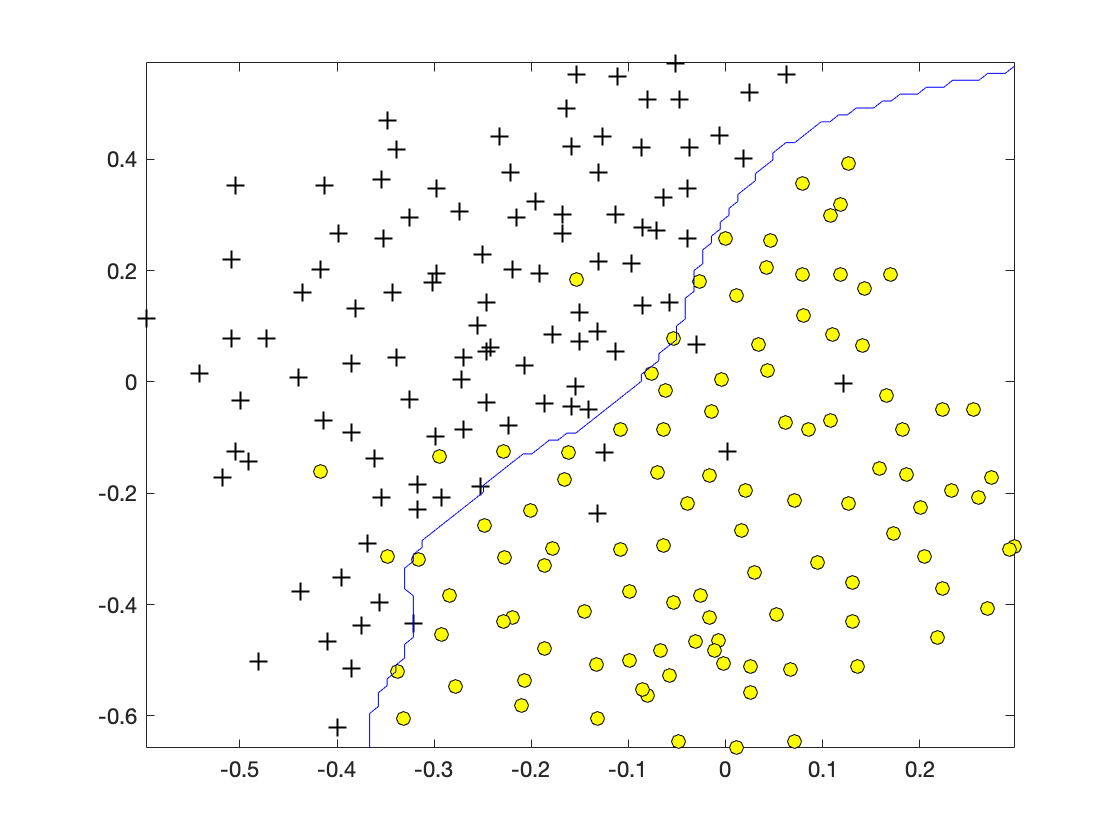

visualizeBoundary(X, y, model);

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## 2. Spam Classification

Many email services today provide spam filters that are able to classify emails into spam and non-spam email with high accuracy. In this part of the exercise, you will use SVMs to build your own spam filter. You will be training a classifier to classify whether a given email, $x$, is spam ($y = 1$) or non-spam ($y = 0$). In particular, you need to convert each email into a feature vector $x\in\mathbb{R}^n$. The following parts of the exercise will walk you through how such a feature vector can be constructed from an email.

    The dataset included for this exercise is based on a a subset of the [SpamAssassin Public Corpus](https://spamassassin.apache.org/old/publiccorpus/). For the purpose of this exercise, you will only be using the body of the email (excluding the email headers).

### 2.1 Preprocessing emails

Before starting on a machine learning task, it is usually insightful to take a look at examples from the dataset. Figure 8 shows a sample email that contains a URL, an email address (at the end), numbers, and dollar amounts. While many emails would contain similar types of entities (e.g., numbers, other URLs, or other email addresses), the specific entities (e.g., the specic URL or specific dollar amount) will be different in almost every email.

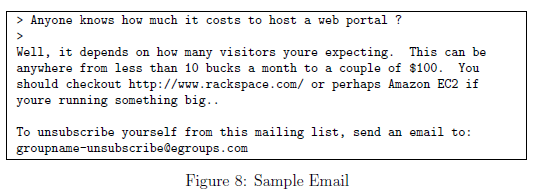

    Therefore, one method often employed in processing emails is to 'normalize' these values, so that all URLs are treated the same, all numbers are treated the same, etc. For example, we could replace each URL in the email with the unique string "httpaddr" to indicate that a URL was present. This has the effect of letting the spam classifier make a classification decision based on whether any URL was present, rather than whether a specific URL was present. This typically improves the performance of a spam classifier, since spammers often randomize the URLs, and thus the odds of seeing any particular URL again in a new piece of spam is very small.

    In `processEmail.m`, we have implemented the following email preprocessing and normalization steps:

- Lower-casing: The entire email is converted into lower case, so that captialization is ignored (e.g., IndIcaTE is treated the same as indicate).

- Stripping HTML: All HTML tags are removed from the emails. Many emails often come with HTML formatting; we remove all the HTML tags, so that only the content remains.

- Normalizing URLs: All URLs are replaced with the text "httpaddr".

- Normalizing Email Addresses: All email addresses are replaced with the text "emailaddr".

- Normalizing Numbers: All numbers are replaced with the text 'number'.

- Normalizing Dollars: All dollar signs ($) are replaced with the text 'dollar'.

- Word Stemming: Words are reduced to their stemmed form. For example, 'discount', 'discounts', 'discounted' and 'discounting' are all replaced with 'discount'. Sometimes, the Stemmer actually strips off additional characters from the end, so 'include', 'includes', 'included', and 'including' are all replaced with 'includ'.

- Removal of non-words: Non-words and punctuation have been removed. All white spaces (tabs, newlines, spaces) have all been trimmed to a single space character.

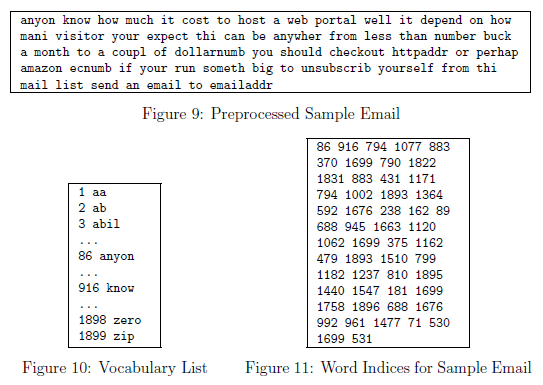

    The result of these preprocessing steps is shown in Figure 9. While preprocessing has left word fragments and non-words, this form turns out to be much easier to work with for performing feature extraction.

#### 2.1.1 Vocabulary list

After preprocessing the emails, we have a list of words (e.g., Figure 9) for each email. The next step is to choose which words we would like to use in our classifier and which we would want to leave out. For this exercise, we have chosen only the most frequently occuring words as our set of words considered (the vocabulary list). Since words that occur rarely in the training set are only in a few emails, they might cause the model to overfit our training set. The complete vocabulary list is in the file vocab.txt and also shown in Figure 10. Our vocabulary list was selected by choosing all words which occur at least a 100 times in the spam corpus, resulting in a list of 1899 words. In practice, a vocabulary list with about 10,000 to 50,000 words is often used.

    Given the vocabulary list, we can now map each word in the preprocessed emails (e.g., Figure 9) into a list of word indices that contains the index of the word in the vocabulary list. Figure 11 shows the mapping for the sample email. Specically, in the sample email, the word 'anyone' was first normalized to 'anyon' and then mapped onto the index 86 in the vocabulary list.

    Your task now is to complete the code in `processEmail.m` to perform this mapping. In the code, you are given a string `str` which is a single word from the processed email. You should look up the word in the vocabulary list `vocabList` and find if the word exists in the vocabulary list. If the word exists, you should add the index of the word into the word indices variable. If the word does not exist, and is therefore not in the vocabulary, you can skip the word.

    Once you have implemented `processEmail.m`, the code below will run your code on the email sample and you should see an output similar to Figures 9 & 11.

**MATLAB Tip**: In MATLAB, you can compare two strings with the `strcmp` function. For example, `strcmp(str1, str2)` will return 1 only when both strings are equal. In the provided starter code, `vocabList` is a 'cell-array' containing the words in the vocabulary. In MATLAB, a cell-array is just like a normal array (i.e., a vector), except that its elements can also be strings (which they can't in a normal MATLAB matrix/vector), and you index into them using curly braces instead of square brackets. Specically, to get the word at index `i`, you can use `vocabList{i}`. You can also use `length(vocabList)` to get the number of words in the vocabulary.

%% Initialization
clear;

% Extract Features
file_contents = readFile('emailSample1.txt');
word_indices  = processEmail(file_contents);


==== Processed Email ====

anyon know how much it cost to host a web portal well it depend on how mani 
visitor you re expect thi can be anywher from less than number buck a month 
to a coupl of dollarnumb you should checkout httpaddr or perhap amazon ecnumb 
if your run someth big to unsubscrib yourself from thi mail list send an 
email to emailaddr 



% Print Stats
disp(word_indices)

          86
         916
         794
        1077
         883
         370
        1699
         790
        1822
        1831
         883
         431
        1171
         794
        1002
        1893
        1364
         592
        1676
         238
         162
          89
         688
         945
        1663
        1120
        1062
        1699
         375
        1162
         479
        1893
        1510
         799
        1182
        1237
         810
        1895
        1440
        1547
         181
        1699
        1758
        1896
         688
        1676
         992
         961
        1477
          71
         530
        1699
         531



*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.2 Extracting features from emails

You will now implement the feature extraction that converts each email into a vector in $\mathbb{R}^n$. For this exercise, you will be using words in vocabulary list. Specically, the feature $x_i\in\{0,\;1\}$for an email corresponds to whether the $i$-th word in the dictionary occurs in the email. That is, $x_i = 1$ if the $i$-th word is in the email and $x_i = 0$ if the $i$-th word is not present in the email.

    Thus, for a typical email, this feature would look like:


$$x=\left\lbrack \begin{array}{c}
0\\
\vdots \\
1\\
0\\
\vdots \\
1\\
0\\
\vdots \\
0
\end{array}\right\rbrack \in R^n$$


You should now complete the code in `emailFeatures.m` to generate a feature vector for an email, given the word indices. Once you have implemented `emailFeatures.m`, the code below will will run your code on the email sample. You should see that the feature vector had length 1899 and 45 non-zero entries.

% Extract Features
features = emailFeatures(word_indices);

% Print Stats
fprintf('Length of feature vector: %d\n', length(features));

Length of feature vector: 1899


fprintf('Number of non-zero entries: %d\n', sum(features > 0));

Number of non-zero entries: 45


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.3 Training SVM for spam classification

After you have completed the feature extraction functions, the code in this section will load a preprocessed training dataset that will be used to train an SVM classifier. `spamTrain.mat` contains 4000 training examples of spam and non-spam email, while `spamTest.mat` contains 1000 test examples. Each original email was processed using the `processEmail` and `emailFeatures `functions and converted into a vector $x^{(i)}\in\mathbb{R}^{1899|$. After loading the dataset, the code will proceed to train a SVM to classify between spam ($y = 1$) and non-spam ($y = 0$) emails. Once the training completes, you should see that the classifier gets a training accuracy of about 99.8% and a test accuracy of about 98.5%.

% Load the Spam Email dataset
% You will have X, y in your environment
load('spamTrain.mat');
C = 0.1;
model = svmTrain(X, y, C, @linearKernel);


Training ......................................................................
...............................................................................
................................................................. Done! 




p = svmPredict(model, X);
fprintf('Training Accuracy: %f\n', mean(double(p == y)) * 100);

Training Accuracy: 99.675000



% Load the test dataset
% You will have Xtest, ytest in your environment
load('spamTest.mat');

p = svmPredict(model, Xtest);
fprintf('Test Accuracy: %f\n', mean(double(p == ytest)) * 100);

Test Accuracy: 98.400000


### 2.4 Top predictors for spam

To better understand how the spam classifier works, we can inspect the parameters to see which words the classifier thinks are the most predictive of spam. The code below finds the parameters with the largest positive values in the classier and displays the corresponding words (Figure 12). Thus, if an email contains words such as 'guarantee', 'remove', 'dollar', and 'price' (the top predictors shown in Figure 12), it is likely to be classied as spam.

% Sort the weights and obtin the vocabulary list
[weight, idx] = sort(model.w, 'descend');
vocabList = getVocabList();
for i = 1:15
    if i == 1
        fprintf('Top predictors of spam: \n');
    end
    fprintf('%-15s (%f) \n', vocabList{idx(i)}, weight(i));
end

Top predictors of spam: 


our             (0.496509) 
click           (0.462307) 
remov           (0.421631) 
guarante        (0.388184) 
visit           (0.370626) 
basenumb        (0.343773) 
dollar          (0.327450) 
price           (0.266223) 
will            (0.266020) 
pleas           (0.263416) 
most            (0.261198) 
lo              (0.257345) 
nbsp            (0.253282) 
ga              (0.245466) 
hour            (0.241635) 


### 2.5 Optional (ungraded) exercise: Try your own emails

Now that you have trained a spam classifier, you can start trying it out on your own emails. In the starter code, we have included two email examples (emailSample1.txt and emailSample2.txt) and two spam examples (spamSample1.txt and spamSample2.txt). The code below runs the spam classifier over the first spam example and classifies it using the learned SVM. You should now try the other examples we have provided and see if the classifier gets them right. You can also try your own emails by replacing the examples (plain text files) with your own emails.

*You do not need to submit any solutions for this optional (ungraded) exercise.*

### 2.6 Optional (ungraded) exercise: Build your own dataset

In this exercise, we provided a preprocessed training set and test set. These datasets were created using the same functions (`processEmail.m` and `emailFeatures.m`) that you now have completed. For this optional (ungraded) exercise, you will build your own dataset using the original emails from the[ SpamAssassin Public Corpus](https://www.google.com/url?sa=t&rct=j&q=&esrc=s&source=web&cd=2&cad=rja&uact=8&ved=0ahUKEwir4Yzi3tfWAhXCRSYKHVy4AzEQFggxMAE&url=https%3A%2F%2Fspamassassin.apache.org%2Fold%2Fpubliccorpus%2F&usg=AOvVaw2WMiDsjzlOHVIdW-QbC__r). Your task in this optional (ungraded) exercise is to download the original files from the public corpus and extract them. After extracting them, you should run the `processEmail*` and `emailFeatures` functions on each email to extract a feature vector from each email. This will allow you to build a dataset `X`, `y` of examples. You should then randomly divide up the dataset into a training set, a cross validation set and a test set.

    While you are building your own dataset, we also encourage you to try building your own vocabulary list (by selecting the high frequency words that occur in the dataset) and adding any additional features that you think might be useful. Finally, we also suggest trying to use highly optimized SVM toolboxes such as [LIBSVM](http://www.csie.ntu.edu.tw/~cjlin/libsvm/) or the [SVM functionality](https://www.mathworks.com/help/stats/support-vector-machine-classification.html) contained within MATLAB's Statistics and Machine Learning Toolbox.

**The original emails will have email headers that you might wish to leave out. We have included code in *`processEmail`* that will help you remove these headers.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored. 

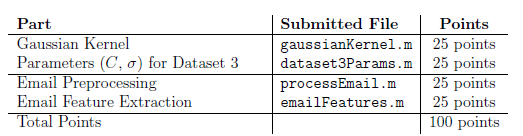

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.